# Detecting arbitrary shape

The basic steps to detect any arbitrary shape are the following. 

However, depending on the image one might need to tweak the details to get optimal results

- Detect edges

- Dilate 

- Fill holes

- Remove noise

- Erode (Smoothen)

- Find perimeter

##                                                                                                          Original

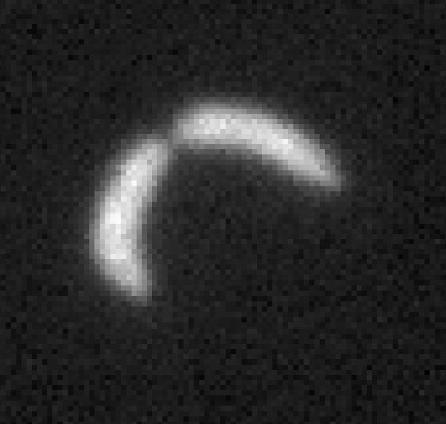

##                                                                                                     Detected Shape

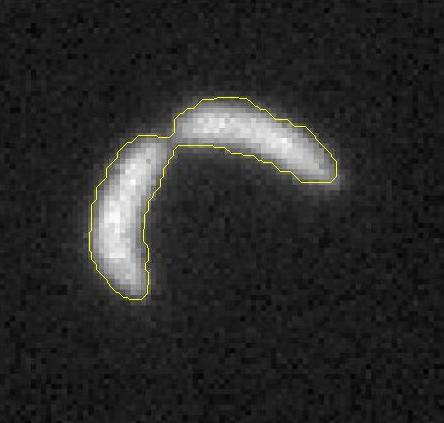

## Read and display image file

Use imread to read the jpg file and imshow to display the image.

The file name you'll need to load is CCfew2.jpg

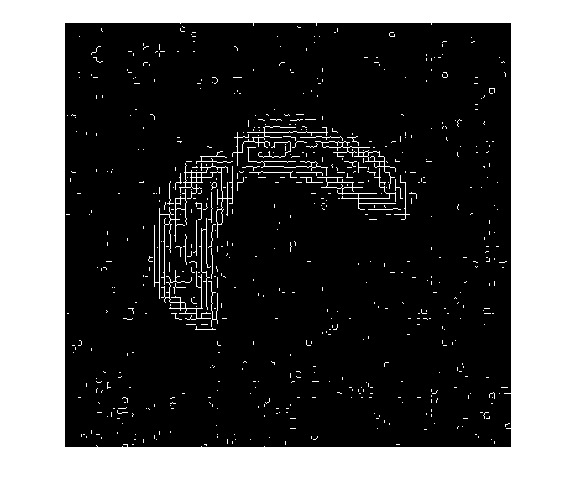

## Detect edge

Use the edge function to detect the edges in the image. We will use the 'Sobel' edge detection algorithm, but feel free to try and see how other algorithms work. use the help command to see the documentation for the function edge. 

Use imshow to display the resulting binary image.

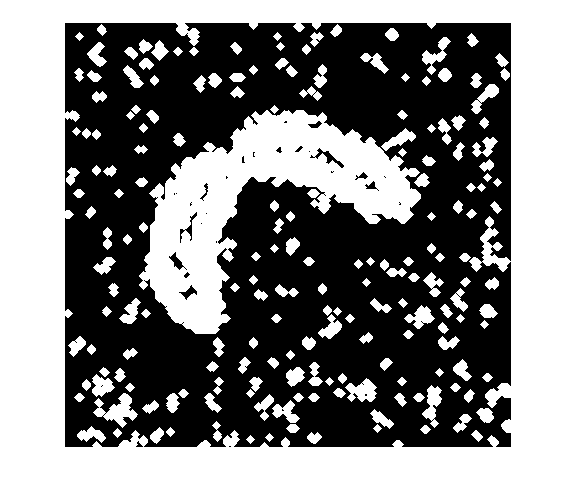

## Dilate image

We will create a structural element shaped like a diamond and dilate the binary image from the edge detection algorithm. 

Use the fuunction strel to create the structural element and imdilate to dilate the image. Finally, use imshow to display the result.

## Fill holes 

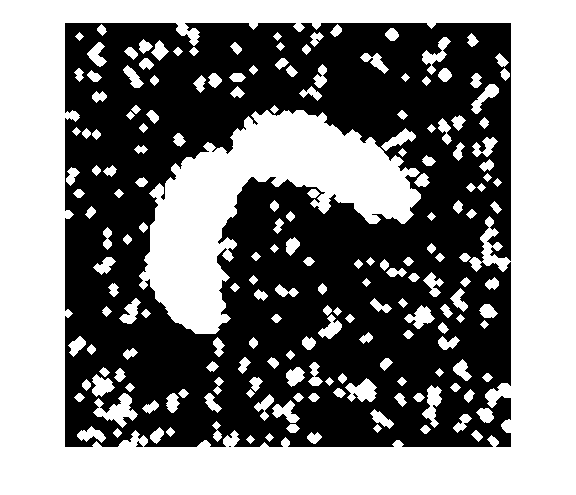

bw_fill = imfill(bw_dil, 'holes');
imshow(bw_fill);

Remove noise pixels

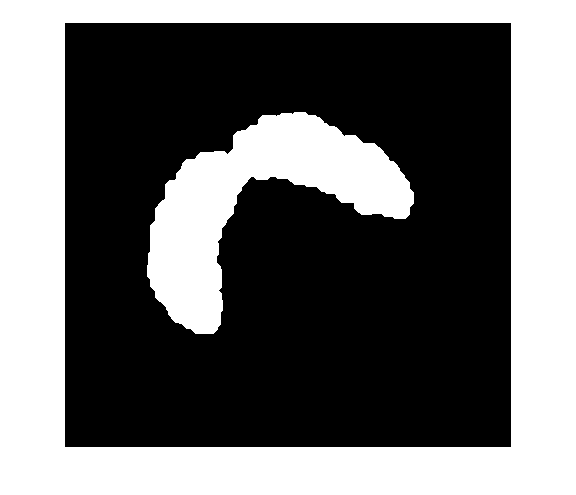

sedisk = strel('disk', 20);
bw_open = imopen(bw_fill, sedisk);
imshow(bw_open);

Smoothen object

sedisk = strel('disk', 8);
bw_smooth = imerode(bw_open, sedisk);
imshow(bw_smooth);

Create perimeter

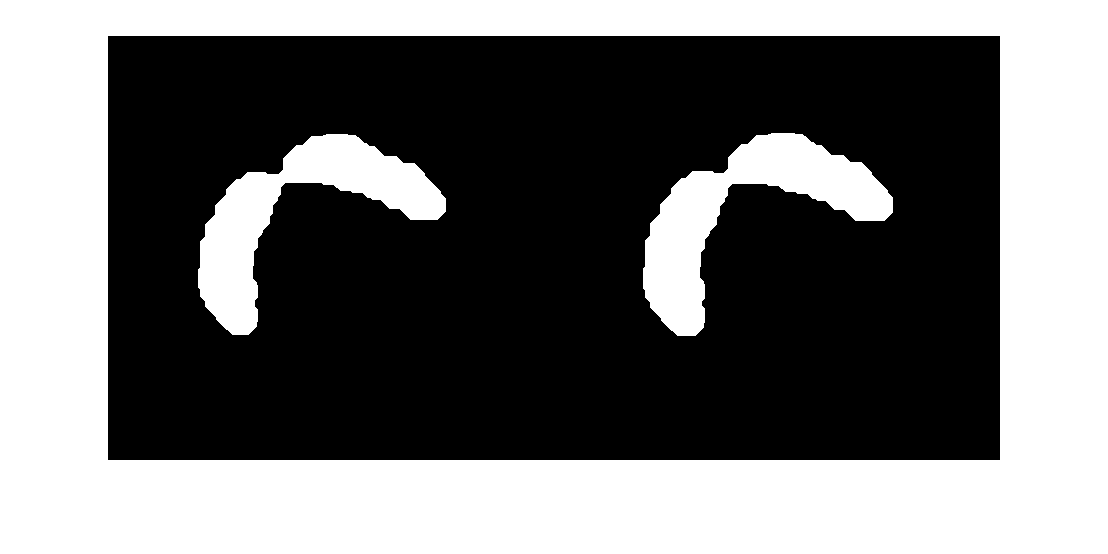

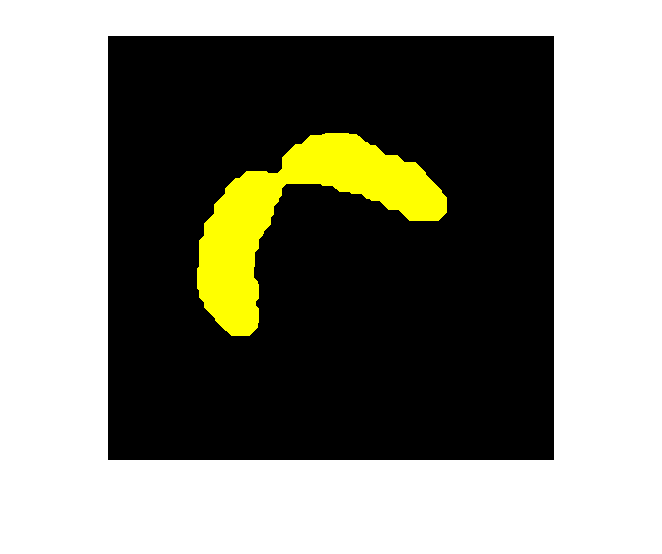

bw_line = bwperim(bw_smooth);

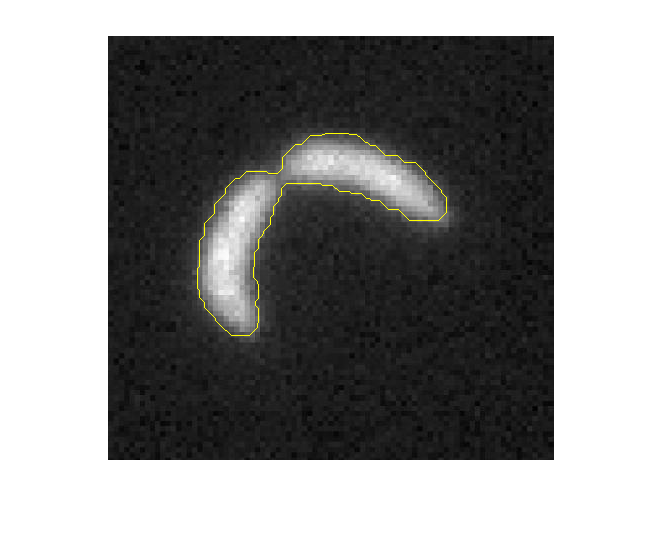

img2 = imoverlay(img1, bw_line); 
imshow(img2)